## * CALISTA MAIN SCRIPT *

## Removing undesired clusters

Example 10. Hematopoietic stem cell differentiation (`Example_2_MOIGNARD_scRT_qPCR.m` script in the main folder of CALISTA)

Analysis of RT-qPCR data in Moignard et al., [Characterization of transcriptional networks in blood stem and progenitor cells using high-throughput single-cell gene expression analysis, Nat. Cell Biol. 15, 363–72 (2013)](https://www.nature.com/articles/ncb2709).

We begin with changing the current directory in MATLAB to the CALISTA folder. Type '`cd`' in the command window then copy and paste the current path in '`curr_path`':

clc
clear all
close all

% Add path for CALISTA folder:
% mfilename=matlab.desktop.editor.getActiveFilename;
% curr_path=fileparts(which(mfilename));

% In windows
 curr_path='C:\Users\npgao\polybox\CALISTA-MATLAB_1.2.2';
% In MacOS
%curr_path='/Users/nan/polybox/CALISTA-MATLAB_1.2.2';

cd(curr_path);
addpath(genpath(curr_path))
warning ('off','all');

## * 1-Data Import and Preprocessing *

Type '`help import_data`' in the command window for more information 

Run the following section and import Moignard dataset (available in the subfolder *EXAMPLES/MOIGNARD*).

%% *** 1-Data Import and Preprocessing ***
%
% Type 'help import_data' for more information 
%
% Specify pre-processing settings
INPUTS.data_type=1; % Single-cell RT-qPCR CT data
INPUTS.format_data=1; % Rows= cells and Columns= genes with time/stage info in the last column
%
% Specify landscape plotting settings
INPUTS.ngrid=40; % Grid size for 2D interpolation
%
% Specify path analysis settings
INPUTS.plot_fig=1; % Plot figure of smoothened gene expression along path
INPUTS.hclustering=1; % Perform hierarchical clustering of gene expression for each path 
INPUTS.method=2; % Use pairwise correlation for the gene co-expression network (value_cutoff=0.8, pvalue_cutoff=0.01)
INPUTS.path_auto=0; % Manually define paths for further analysis

% Upload and pre-process data 
[DATA,INPUTS] = import_data(INPUTS);



**** Please upload normalized data. File formats accepted: .txt , .xlxs , .csv, .mat, .loom ****


Filtering genes by number of cells...

Filtering cells by number of genes...

% of zeros in the data  0.00

Selecting most variable genes...

Normalizing the data...

Finishing setup of the CALISTA data structure...

DONE.


## * 2-SINGLE-CELL CLUSTERING *

Type '`help CALISTA_clustering_main`' in the command window for more information. 

Following the original publication, we set the number of clusters equals to **5** in the command window:

Starting parallel pool (parpool) using the 'local' profile ...
connected to 6 workers.

CALISTA_clustering is running...
Progress:
..................................................
||||||||||||||||||||||||||||||||||||||||||||||||||

Performing clustering based on consensus matrix...

Constructing consensus matrix...

Kmedois...
Elapsed time is 35.196382 seconds.

Plotting...


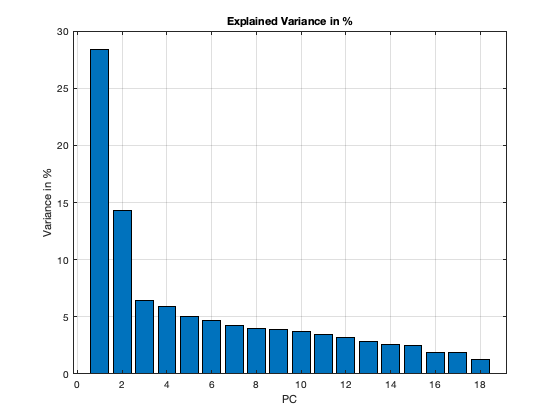

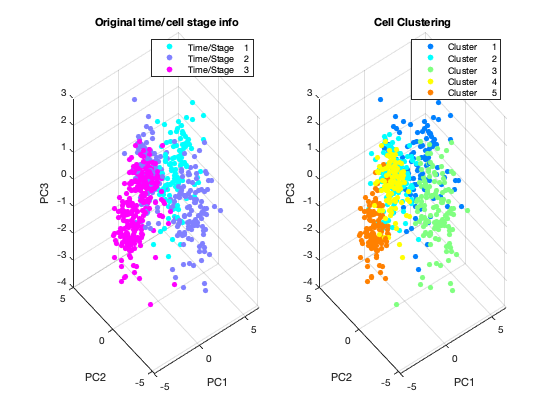

Elapsed time is 41.208409 seconds.

DONE.


[Results, DATA, INPUTS]=CALISTA_clustering_main(DATA,INPUTS);

%  Cluster removal (if desired)
cluster_cut=input('Press 1 if you want to remove cell cluster(s). Press 0 otherwise: ');

if cluster_cut==1
    
   which_cut=input('Enter cluster index for removal (e.g 1 or [5 3]): ');
   cells_2_cut2=find(ismember(Results.final_groups,which_cut)==1);
   cells_2_cut2=DATA.cut_sort.abs_indices(cells_2_cut2);
   csvwrite('Cells_2_remove',cells_2_cut2)   
   RESULTS.cluster_cut = 1;
   fprintf('Cell''s indices to remove are saved in "Cells_2_remove.csv". Please run MAIN script again \n')
   return
end

Cell's indices to remove are saved in "Cells_2_remove.csv". Please run MAIN script again 


Let us proceed with removing cluster 3 and 5, by entering `1 `and type `[5 3] `upon queried.

The indices of cells to remove are saved in a csv file.

We then edit MAIN.m script again, but we set the INPUTS as described previously except:

INPUTS.cells_2_cut=1; % Manual removal of cells

We run MAIN.m once more from the workspace and import Moignard dataset (in subfolder EXAMPLES/RTqPCR).

We also upload the csv file containing cell’s indices to remove.

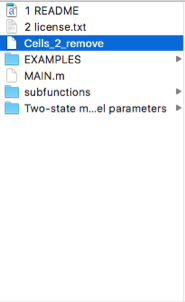

% Upload and pre-process data 
[DATA,INPUTS] = import_data(INPUTS);



**** Please upload normalized data. File formats accepted: .txt , .xlxs , .csv, .mat, .loom ****



**** Select the csv file containing cell indices to remove ****


Filtering genes by number of cells...

Filtering cells by number of genes...

% of zeros in the data  0.00

Selecting most variable genes...

Normalizing the data...

Finishing setup of the CALISTA data structure...

DONE.


We now set the number of clusters equals to **3**.


CALISTA_clustering is running...
Progress:
..................................................
||||||||||||||||||||||||||||||||||||||||||||||||||

Performing clustering based on consensus matrix...

Constructing consensus matrix...

Kmedois...
Elapsed time is 1.248529 seconds.

Plotting...


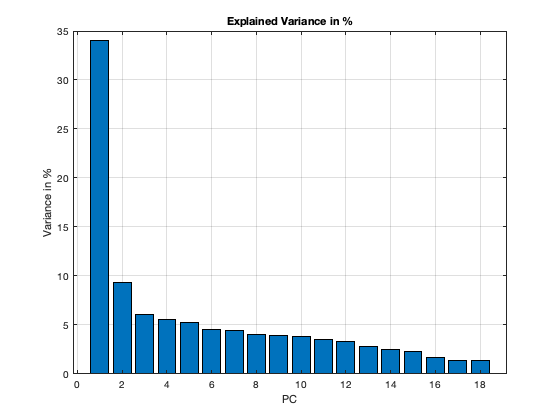

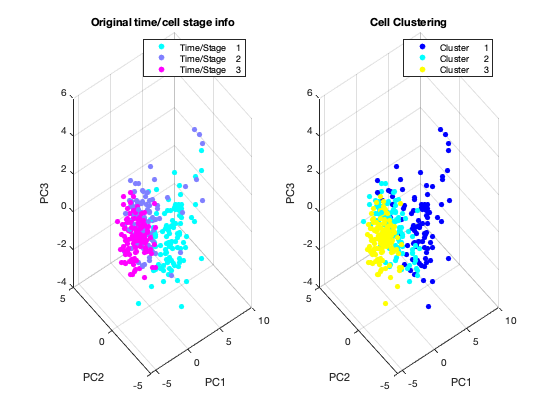

Elapsed time is 4.953390 seconds.

DONE.


[Results, DATA, INPUTS]=CALISTA_clustering_main(DATA,INPUTS);

## * 3-RECONSTRUCTION OF LINEAGE PROGRESSION *

Type '`help CALISTA_transition_main`' in the command window for more information. 

Here, we do not need to remove any spurious edges, and hence we enter 0 upon queried:


CALISTA_transition is running...



2 edge(s) have been added and the graph is connected. 
If you want to add another edge press "p" 
If you want to remove an edge press "m" 
If you want to continue with the next step press "enter" 
(Please make sure that figure 101 is in the foreground and no additional tools are selected (e.g. zooming, rotation, data cursor etc.)) 

----------------------------------------------



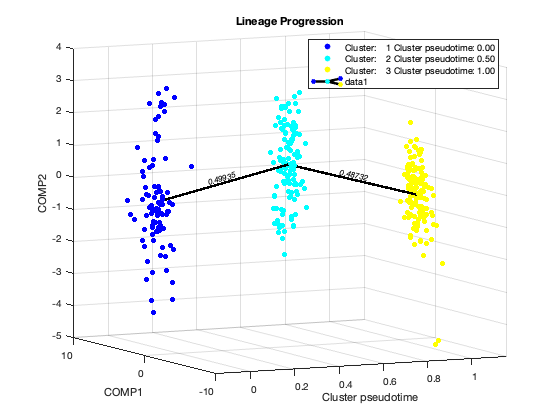

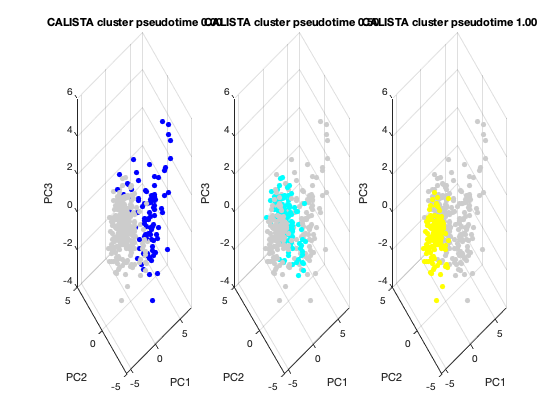

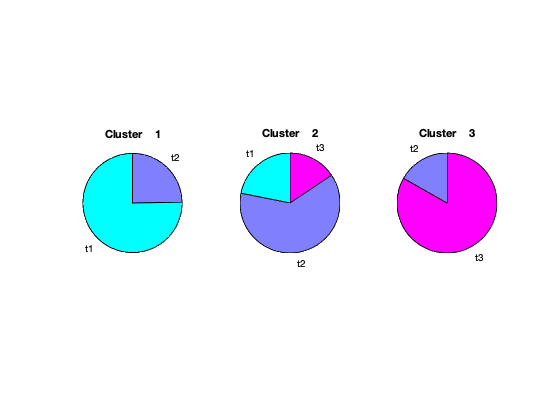


Plotting mean gene expressions...


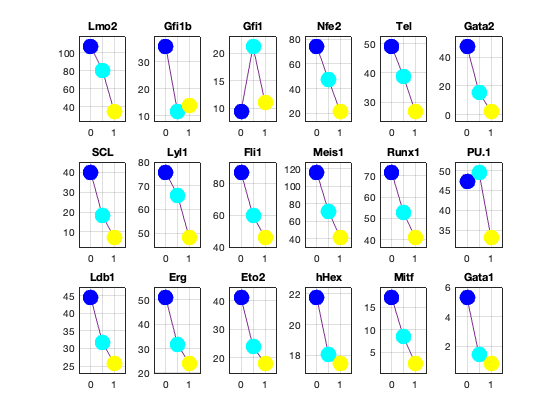


DONE.


[Results]=CALISTA_transition_main(DATA,INPUTS,Results);

% % Save 3D video
% figure(100)
% % daspect([2,2,0.3]);
% OptionZ.FrameRate=20;OptionZ.Duration=20.5;OptionZ.Periodic=true;
% CaptureFigVid([-20,10;-110,10;-190,80;-290,10;-380,10], 'CALISTA_lineage_3Dvideo',OptionZ)

## * 4-DETERMINATION OF TRANSITION GENES *

Type '`help CALISTA_transition_genes_main`' in the command window for more information. 

After reconstructing the lineage progression, we identify the key transition genes for any two connected clusters in the graph, based on the gene-wise likelihood difference between having the cells separately as two clusters and together as a single cluster. Larger differences in the gene-wise likelihood point to more informative genes. The transition genes are selected as those whose gene-wise likelihood differences make up to more than a certain percentage of the cumulative sum of the likelihood differences of all genes – set by` INPUTS.thr_transition_genes`.

[Results]=CALISTA_transition_genes_main(DATA,INPUTS,Results);


CALISTA_transition_genes is running...

DONE.


## * 5-PSEUDOTEMPORAL ORDERING OF CELLS *

Type '`help CALISTA_ordering_main`' in the command window for more information. 

For pseudotemporal ordering of cells, CALISTA performs maximum likelihood optimization for each cell using a linear interpolation of the cell likelihoods between any two connected clusters. The pseudotimes of the cells are computed by linear interpolation of the cluster pseudotimes, and correspond to the maximum point of the likelihood optimization above. Cells are subsequently assigned to the edges in the lineage progression graph. The following screenshot gives the results of this cell-to-edge assignment.


CALISTA_ordering is running...


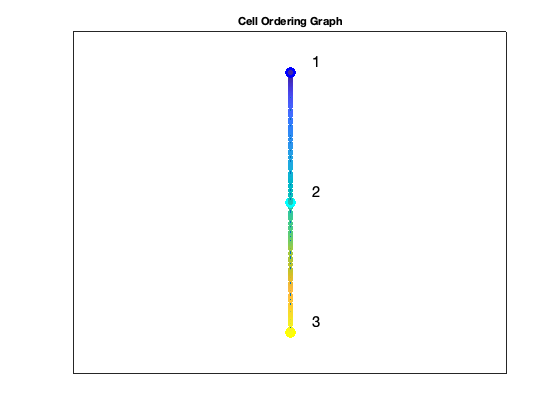


Waiting for plots...


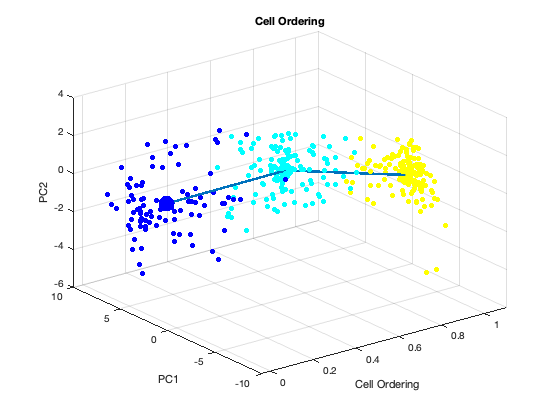


DONE.


[Results]=CALISTA_ordering_main_2(DATA,INPUTS,Results);

% [Results_transition_genes]=CALISTA_ordering_main_2_transition_genes(DATA,INPUTS,Results);